# **Lec15 | Numerical Differentiation**

### **Just transform math expressions into MATLAB code**

Use **Richardson extrapolation** to estimate the first derivative of  

y = -0.1x^4 - 0.15x^3 - 0.5x^2 - 0.25x + 1.2 

at x = 0.5 using step sizes of h1 = 0.5 and h2 = 0.25. 

Employ centered differences of  O(h^2) for the initial estimates.

f = @(x) -0.1*x.^4 - 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.2

f = 値をもつ function_handle :
    @(x)-0.1*x.^4-0.15*x.^3-0.5*x.^2-0.25*x+1.2


True value *(analytic; differentiate once)*

% given in the question
xi = 0.5

xi = 0.5000

h1 = 0.5 % step size

h1 = 0.5000

h2 = 0.25 % step size

h2 = 0.2500


df = @(x) -0.4*x.^3 - 0.45*x.^2 - x - 0.25

df = 値をもつ function_handle :
    @(x)-0.4*x.^3-0.45*x.^2-x-0.25


diff_xi_true = df(xi) % true first derivative

diff_xi_true = -0.9125

# Using step size $h_1$ = 0.5

xi1 = xi + h1; % x of i + 1
xi_1 = xi - h1; % x of i - 1

**Centered difference **approximation of the first derivative O(h^2)   using step size = h1

centered_Oh2_steph1 = (f(xi1) - f(xi_1)) / (2*h1)

centered_Oh2_steph1 = -1

err_centered_Oh2_steph1 = ((diff_xi_true - centered_Oh2_steph1) / diff_xi_true) * 100

err_centered_Oh2_steph1 = -9.5890

# Using step size $h_2$ = 0.25

xi1 = xi + h2; % x of i + 1
xi_1 = xi - h2; % x of i - 1

**Centered difference** approximation of the first derivative O(h^2)   using step size = h2

centered_Oh2_steph2 = (f(xi1) - f(xi_1)) / (2*h2)

centered_Oh2_steph2 = -0.9344

err_centered_Oh2_steph2 = ((diff_xi_true - centered_Oh2_steph2) / diff_xi_true) * 100

err_centered_Oh2_steph2 = -2.3973

# Richardson's

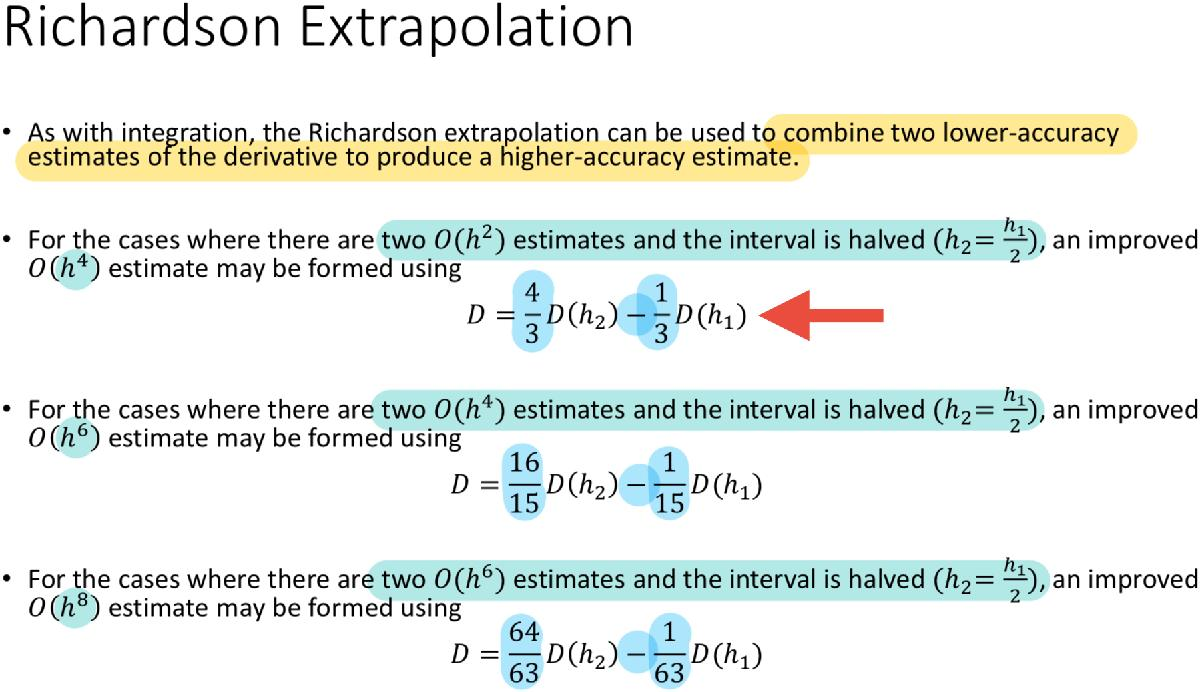

**Richardson extrapolation**: Improved estimate with O(h^4) of the first derivative

centered_Oh4 = (4/3)*centered_Oh2_steph2 - (1/3)*centered_Oh2_steph1

centered_Oh4 = -0.9125

err_centered_Oh4 = ((diff_xi_true - centered_Oh4) / diff_xi_true) * 100

err_centered_Oh4 = -3.6500e-14